NumBits = 1000000

NumBits = 1000000

bitsToSend = randi(2, [NumBits,1]) - 1

bitsToSend =      1
     1
     1
     1
     1
     1
     1
     1
     0
     0


constellation = 1/sqrt(2)*[1+1j; -1+1j; -1-1j; 1-1j]

constellation =    0.7071 + 0.7071i
  -0.7071 + 0.7071i
  -0.7071 - 0.7071i
   0.7071 - 0.7071i


R = log2(length(constellation))

R = 2

% modulation
modSymbols = myModulator(bitsToSend, constellation)

modSymbols =    0.7071 - 0.7071i
  -0.7071 - 0.7071i
   0.7071 - 0.7071i
  -0.7071 - 0.7071i
   0.7071 - 0.7071i
   0.7071 - 0.7071i
   0.7071 - 0.7071i
  -0.7071 - 0.7071i
  -0.7071 + 0.7071i
   0.7071 + 0.7071i


len = length(modSymbols);

% channel
unitNoise = (randn(len, 1)) + 1j*(randn(len, 1))

unitNoise =   -0.4729 + 0.3797i
   1.8074 - 1.0005i
  -0.5658 + 0.6918i
   0.2355 - 0.1695i
  -1.2080 - 1.4420i
   0.0299 - 1.1821i
   1.5309 - 0.6536i
   0.8888 - 0.6968i
  -0.4192 - 0.9254i
   0.1755 + 1.8358i


Noise = unitNoise

Noise =   -0.4729 + 0.3797i
   1.8074 - 1.0005i
  -0.5658 + 0.6918i
   0.2355 - 0.1695i
  -1.2080 - 1.4420i
   0.0299 - 1.1821i
   1.5309 - 0.6536i
   0.8888 - 0.6968i
  -0.4192 - 0.9254i
   0.1755 + 1.8358i


Noisy_modSymbols = modSymbols + Noise

Noisy_modSymbols =    0.2342 - 0.3274i
   1.1003 - 1.7076i
   0.1413 - 0.0153i
  -0.4716 - 0.8766i
  -0.5009 - 2.1492i
   0.7370 - 1.8892i
   2.2380 - 1.3607i
   0.1817 - 1.4039i
  -1.1263 - 0.2183i
   0.8826 + 2.5429i


% de modulation
[decModSymbols, detBits] = myDemodulator(Noisy_modSymbols, constellation);
[detBits, bitsToSend]

ans =      1     1
     1     1
     1     1
     1     1
     1     1
     1     1
     1     1
     1     1
     1     0
     0     0


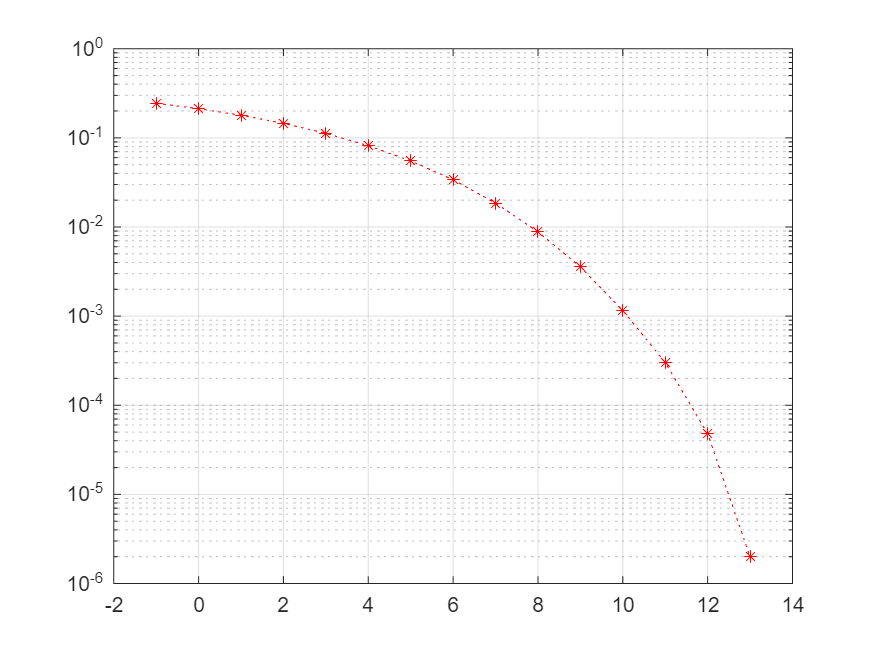

EbNodb = -1:1:15;
BER = zeros(1, length(EbNodb));
for ii = 1:length(EbNodb)
    
    EbNo = 10^(EbNodb(ii)/10);   
    sigma = sqrt(1/(2*EbNo));
    Noise = sigma.*unitNoise;
    Noisy_modSymbols = modSymbols + Noise ;

    [decModSymbols, detBits] = myDemodulator(Noisy_modSymbols, constellation);

    BER(1,ii) = sum(detBits ~= bitsToSend)/NumBits;

end

p = semilogy(EbNodb, BER);
p.LineStyle = ":";
p.Color = "red";
p.Marker = "*";
grid()


SNR_DB = -1:.2:15;
BER = zeros(1,length(SNR_DB));
for ii = 1:length(SNR_DB)
        
     SNR = 10^SNR_DB(ii)/10;
     Noise = unitNoise/SNR;
     Noisy_modSymbols = modSymbols + Noise;

     [decModSymbols, detBits] = myDemodulator(Noisy_modSymbols, constellation);
     BER(1,ii) = sum(detBits ~= bitsToSend)/NumBits;

end

p = semilogy(SNR_DB, BER);
p.LineStyle = ":";
p.Color = "red";
p.Marker = "*";
grid()